# EXERCISE 6

## 1.Signal Creation

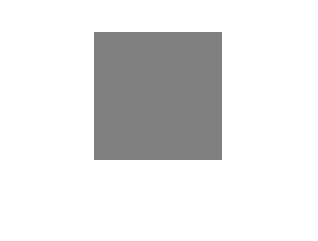

%a
A = 0.5*ones(128);
imshow(A)

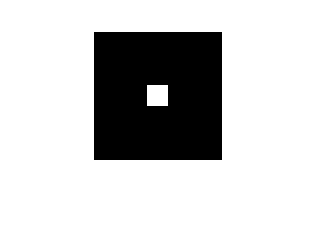


%b
B = zeros(128);
B(54:54+20,54:54+20) = 1;
imshow(B)

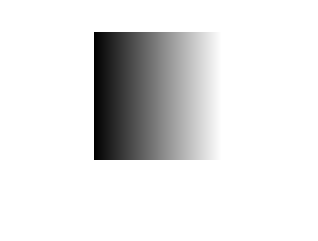


%c
delta = 1/127;
a = ones(128,1);
t=(0:delta:1);
C = a*t;
imshow(C)

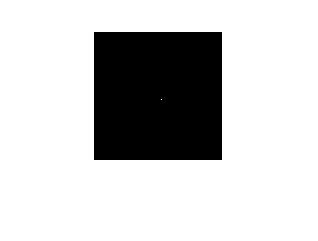


%d
D = zeros(128,128);
D(68,68) = 1;
imshow(D)

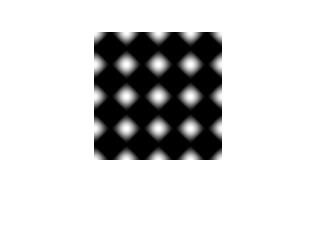


%e
%doc meshgrid
x=0:1:127;
cosine = cos(x*2*pi/32);
[fe_1,fe_2] = meshgrid(cosine,cosine);
E = (fe_1+fe_2)/2;
imshow(E)

## 2.DFT

I use directional fiter 135 degree to implement DFT

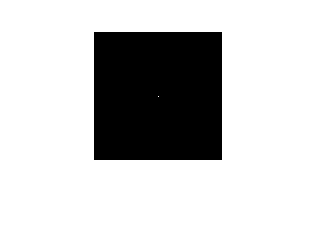

F = fft2(A);
Fc = fftshift(F);
imshow(log(abs(Fc))+0.0001)


filter_ = eye(128);
filter_ = filter_ ./ sum(filter_, [1, 2]);
G = filter_.*Fc;
gi = ifft2(ifftshift(G));
g = real(gi)

g =     0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039
    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0

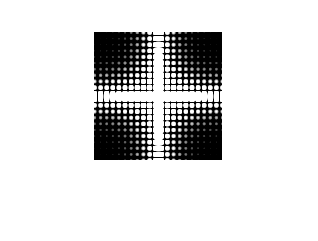

F = fft2(B);
Fc = fftshift(F);
imshow(log(abs(Fc))+0.0001)


filter_ = eye(128);
filter_ = filter_ ./ sum(filter_, [1, 2]);
G = filter_.*Fc;
gi = ifft2(ifftshift(G));
g = real(gi)

g =     0.0012    0.0011    0.0010    0.0010    0.0009    0.0009    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0004    0.0004    0.0003    0.0002    0.0002    0.0001    0.0001         0   -0.0000   -0.0000    0.0000    0.0000         0    0.0000         0    0.0000         0         0    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000         0         0   -0.0000         0    0.0000   -0.0000   -0.0000   -0.0000    0.0000         0
    0.0011    0.0010    0.0010    0.0009    0.0009    0.0008    0.0007    0.0007    0.0006    0.0005    0.0005    0.0004    0.0004    0.0003    0.0002    0.0002    0.0001    0.0001   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0   -0.0000         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000         0         0     

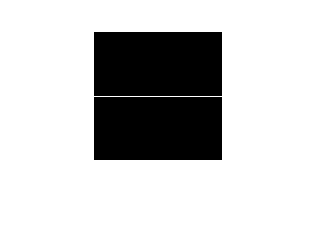

figure,
filter_ = eye(128);
F = fft2(C);
Fc = fftshift(F);
imshow(log(abs(Fc))+0.0001)

filter_ = filter_ ./ sum(filter_, [1, 2]);
G = filter_.*Fc;
gi = ifft2(ifftshift(G));
g = real(gi)

g =     0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039
    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0.0039    0

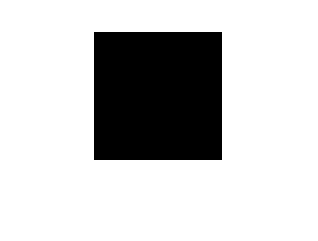

figure,
F = fft2(D);
Fc = fftshift(F);
imshow(log(abs(Fc))+0.0001)


filter_ = eye(128);
filter_ = filter_ ./ sum(filter_, [1, 2]);
G = filter_.*Fc;
gi = ifft2(ifftshift(G));
g = real(gi)

g = 	1.0e+-4 *

         0         0    0.0000         0         0         0    0.6104         0         0         0    0.0000         0         0         0   -0.0000         0         0         0    0.0000         0         0         0    0.0000         0         0         0   -0.0000         0         0         0    0.0000         0         0         0   -0.0000         0         0         0         0         0         0         0    0.0000         0         0         0   -0.0000         0         0         0
         0   -0.0000         0         0         0    0.6104         0         0         0   -0.0000         0         0         0   -0.0000         0         0         0    0.0000         0         0         0    0.0000         0         0         0    0.0000         0         0         0    0.0000         0         0         0   -0.0000         0         0         0   -0.0000         0         0         0    0.0000         0         0         0   -0.0000         0         0   

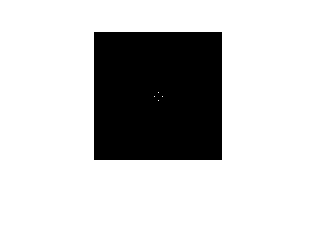

figure,
F = fft2(E);
Fc = fftshift(F);
imshow(log(abs(Fc))+0.0001)


filter_ = eye(128);
filter_ = filter_ ./ sum(filter_, [1, 2]);
G = filter_.*Fc;
gi = ifft2(ifftshift(G));
g = real(gi)

g = 	1.0e+-18 *

   -0.4768   -0.3778   -0.5207   -0.5330   -0.4315   -0.4793   -0.3948   -0.3956   -0.4374   -0.4766   -0.4316   -0.4370   -0.4362   -0.4658   -0.3999   -0.4671   -0.4292   -0.4777   -0.4280   -0.4470   -0.4401   -0.4160   -0.3887   -0.3896   -0.4054   -0.4653   -0.3781   -0.4329   -0.5015   -0.4177   -0.4243   -0.3156   -0.4158   -0.4710   -0.4360   -0.4619   -0.4145   -0.4996   -0.3880   -0.3990   -0.4103   -0.4529   -0.4452   -0.4438   -0.4311   -0.4624   -0.4007   -0.4671   -0.4292   -0.4760
   -0.3778   -0.5207   -0.5330   -0.4315   -0.4793   -0.3948   -0.3956   -0.4374   -0.4766   -0.4316   -0.4370   -0.4362   -0.4658   -0.3999   -0.4671   -0.4292   -0.4777   -0.4280   -0.4470   -0.4401   -0.4160   -0.3887   -0.3896   -0.4054   -0.4653   -0.3781   -0.4329   -0.5015   -0.4177   -0.4243   -0.3156   -0.4158   -0.4710   -0.4360   -0.4619   -0.4145   -0.4996   -0.3880   -0.3990   -0.4103   -0.4529   -0.4452   -0.4438   -0.4311   -0.4624   -0.4007   -0.4671   -0.4292  

## 3.Filtering in the freq domain

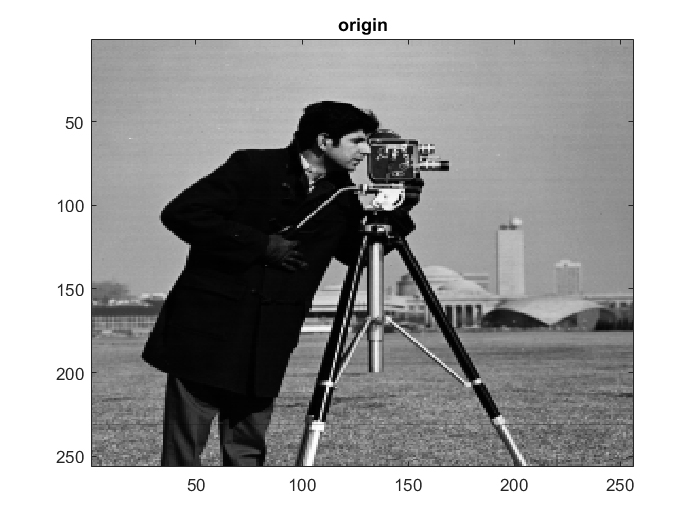

D0 = 20;
n = 2;
I = imread('cameraman.tif');
colormap('gray');
imagesc(I),title('origin')

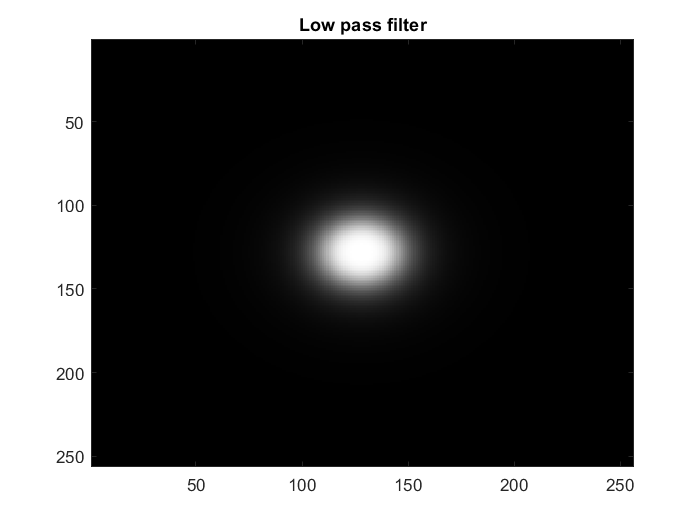

fdi = fftshift(fft2(double(I)));

figure,colormap('gray')
imagesc(BWLPfilter(I,D0,n));title('Low pass filter')

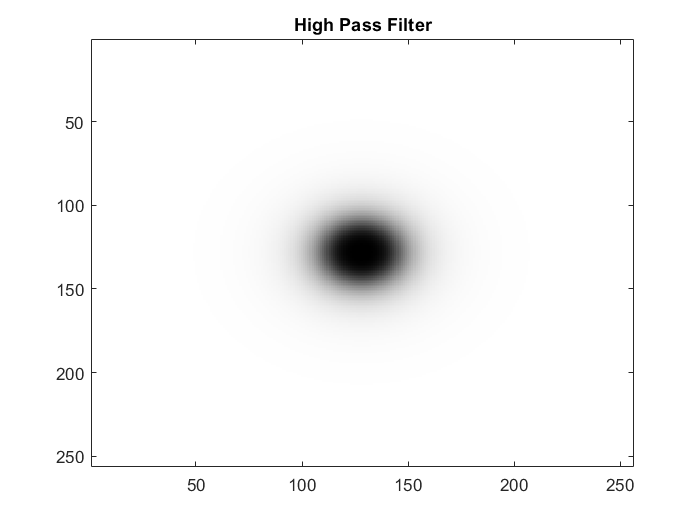

figure,colormap('gray')
imagesc(1-BWLPfilter(I,D0,n));title('High Pass Filter')

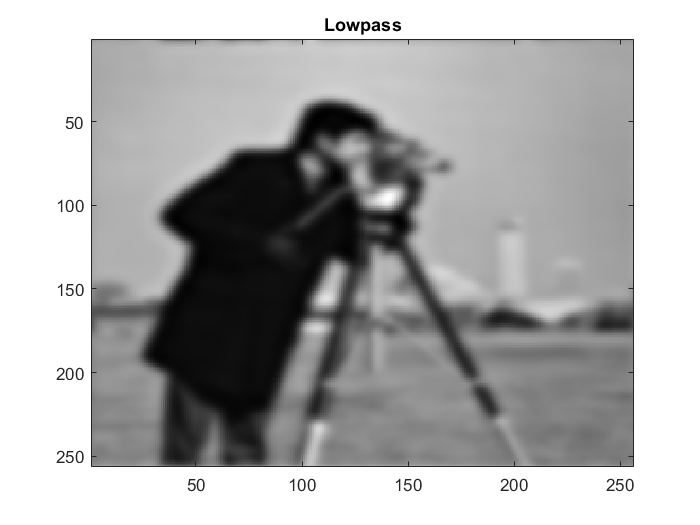

lpf = BWLPfilter(I,D0,n).*fdi;
hpf = 1-BWLPfilter(I,D0,n).*fdi;


figure,
inv_im = real(ifft2(ifftshift(lpf)));
colormap('gray')
imagesc(inv_im),title('Lowpass')

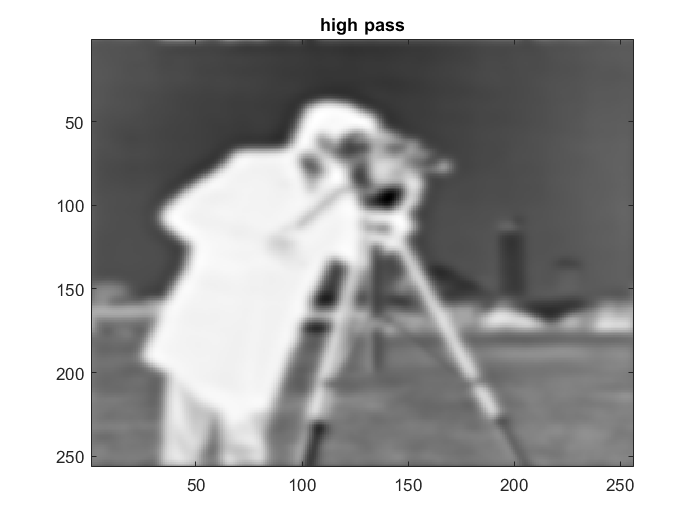


figure,
inv_im = real(ifft2(ifftshift(hpf)));
colormap('gray')
imagesc(inv_im),title('high pass')